% To evaluate the accuracy of semantic segmentation
% by William Dong

%directory and datastore
dataDir = '';
outputDir = fullfile(dataDir, '/');
gtruDir = fullfile(dataDir, '/');
output = imageDatastore(outputDir);
gtru = imageDatastore(gtruDir);

iou = 0

iou = 0

bfs = 0

bfs = 0

iou = 0.9610

bfs = 0.9647

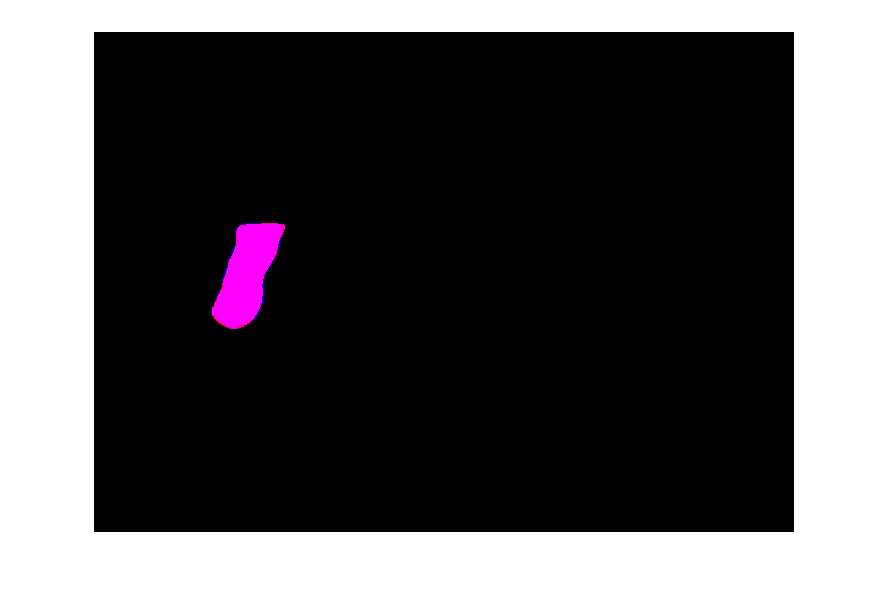

iou = 1.9283

bfs = 1.9340

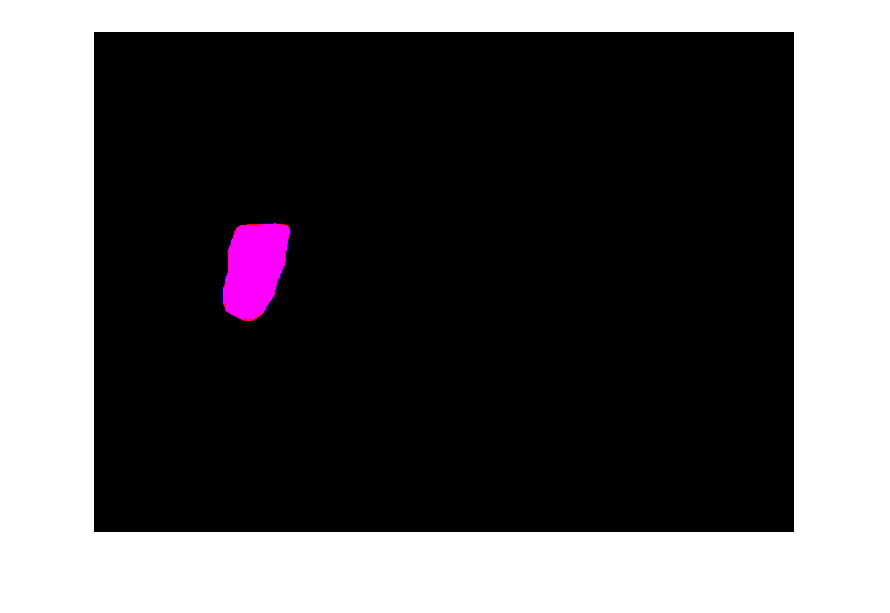

iou = 2.8826

bfs = 2.8937

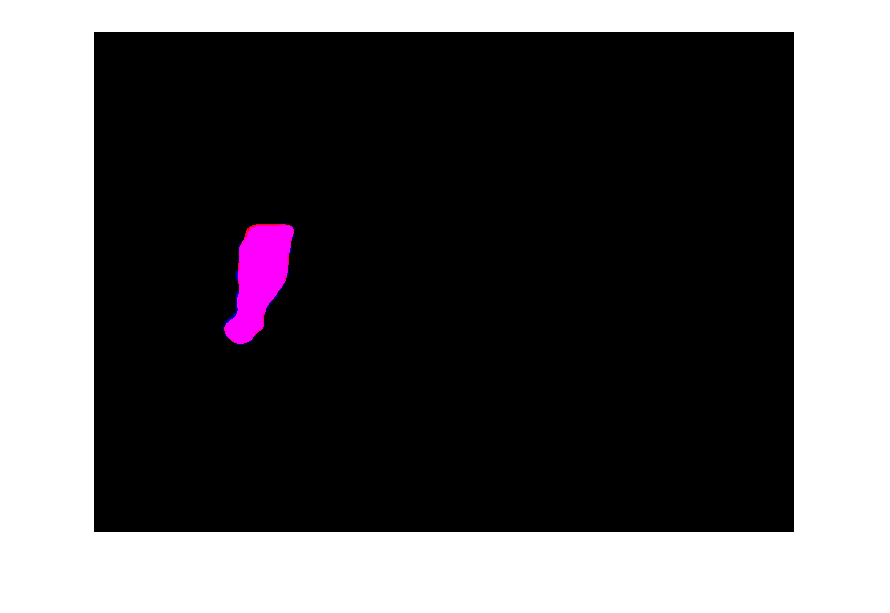

iou = 3.8323

bfs = 3.8491

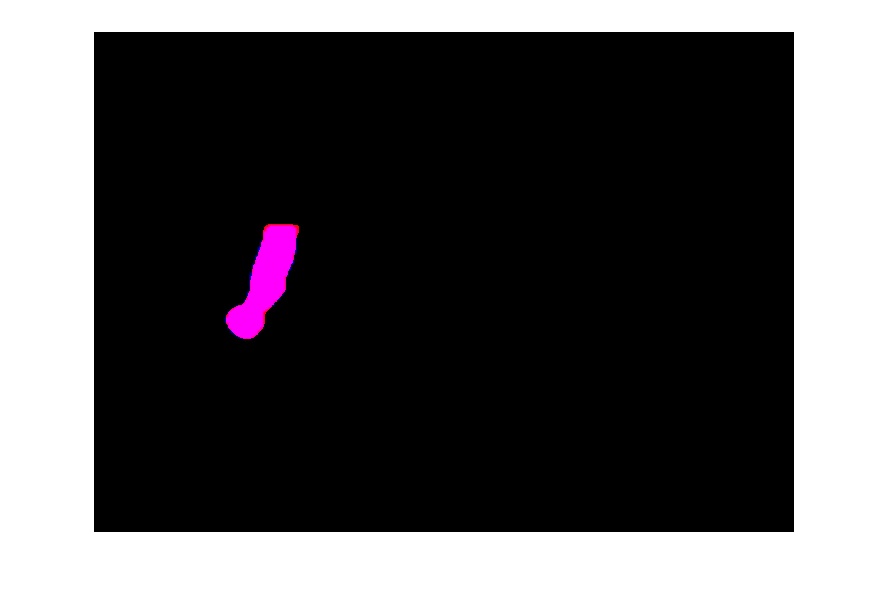

iou = 4.8001

bfs = 4.8194

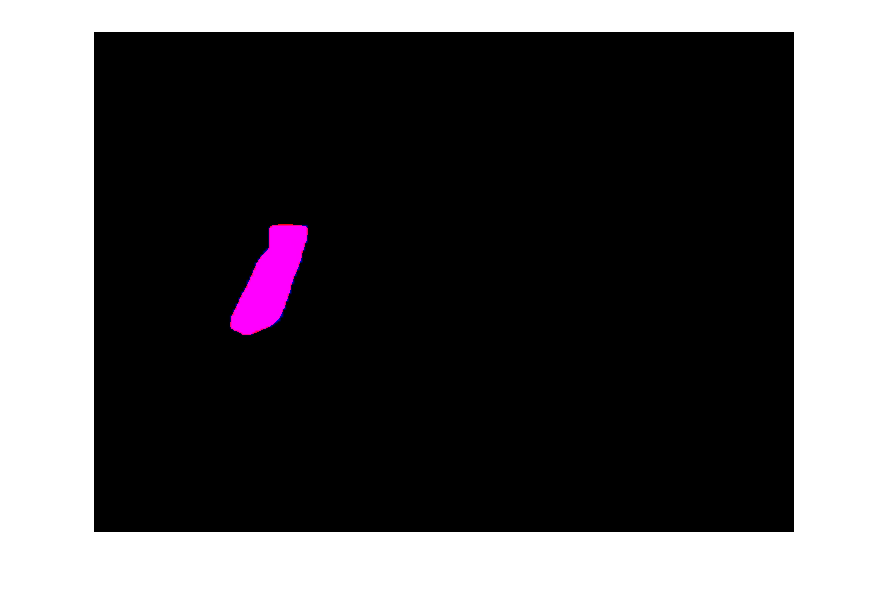

iou = 5.7466

bfs = 5.7720

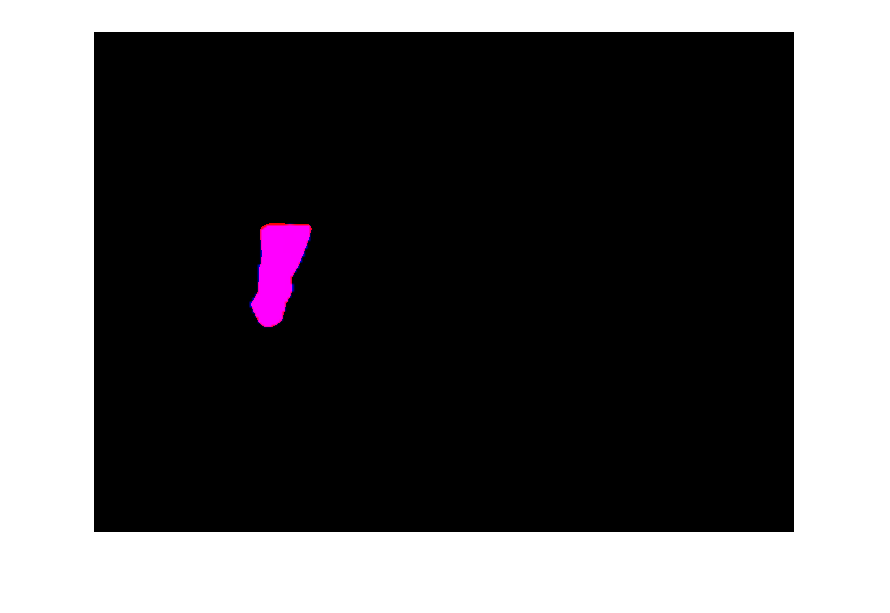

iou = 6.6972

bfs = 6.7282

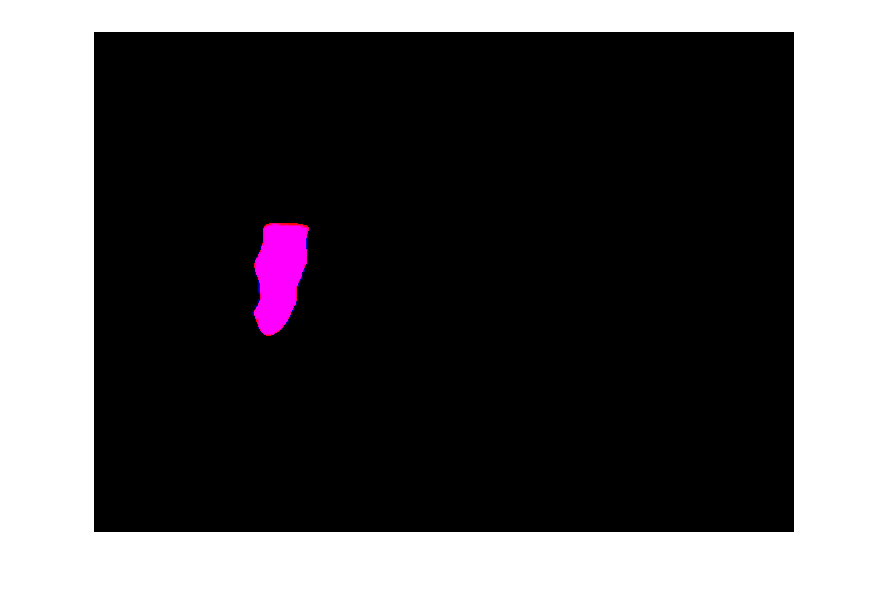

iou = 7.6646

bfs = 7.6981

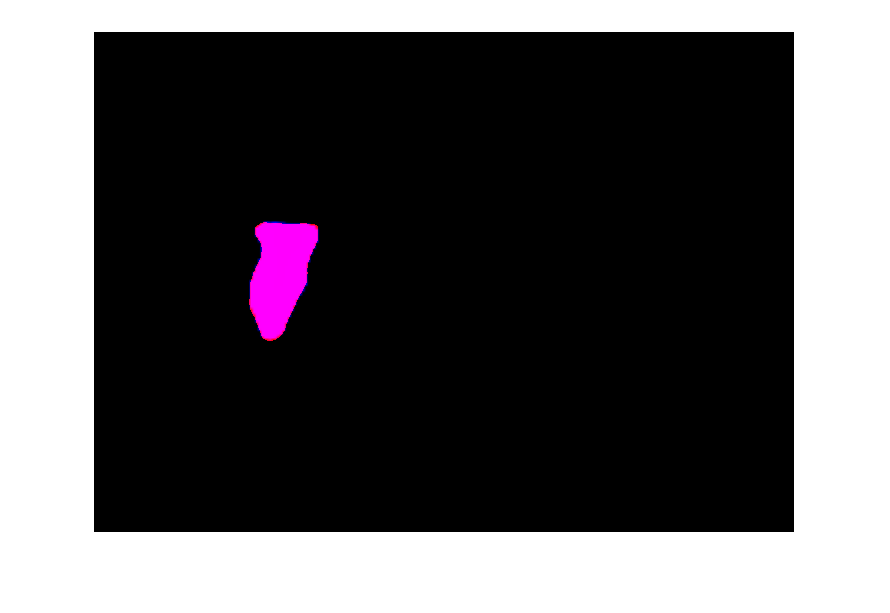

iou = 8.6249

bfs = 8.6661

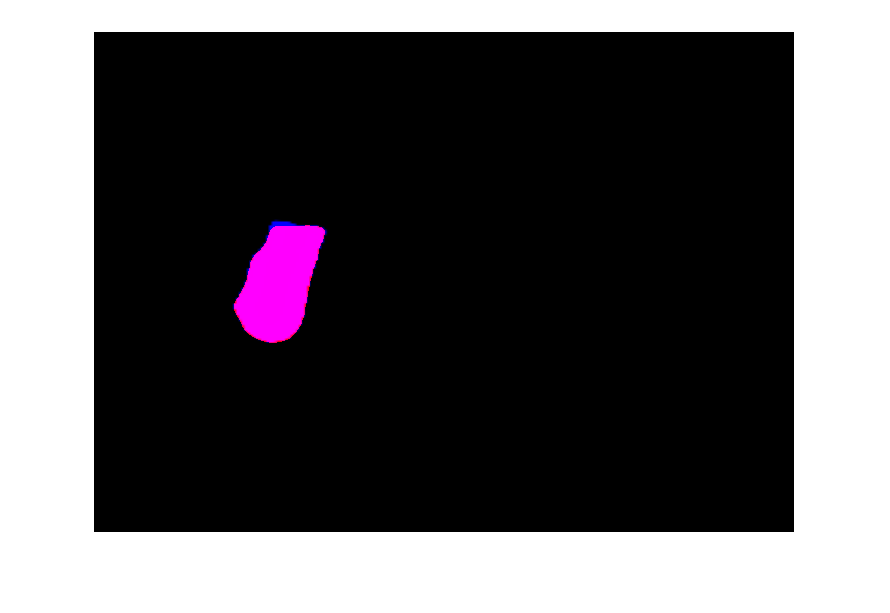

iou = 9.5524

bfs = 9.6136

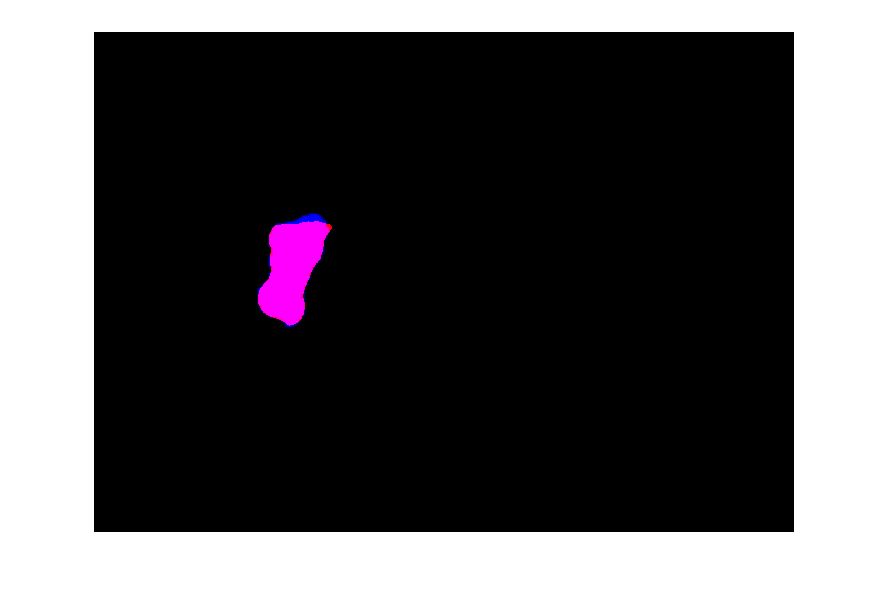

iou = 10.5184

bfs = 10.5822

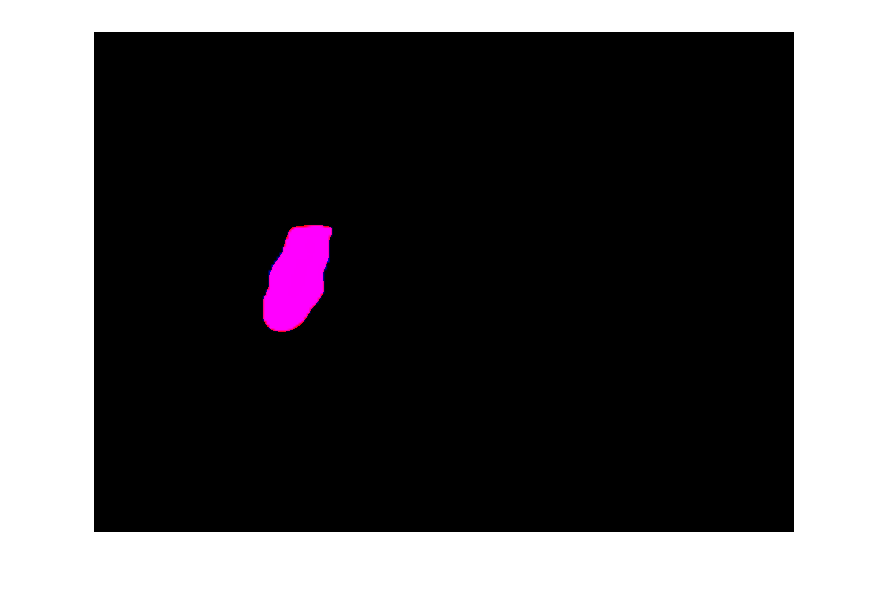

iou = 11.4746

bfs = 11.5443

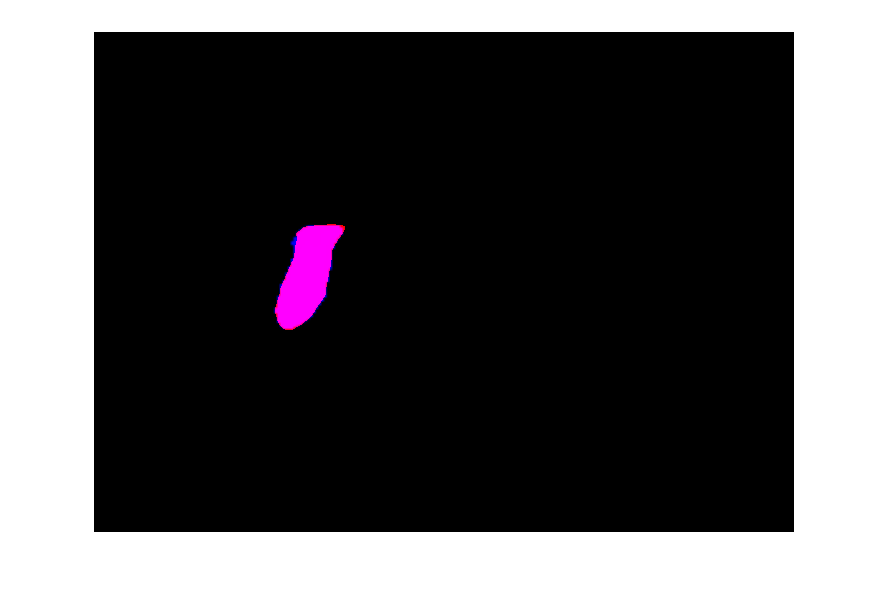

iou = 12.4330

bfs = 12.5072

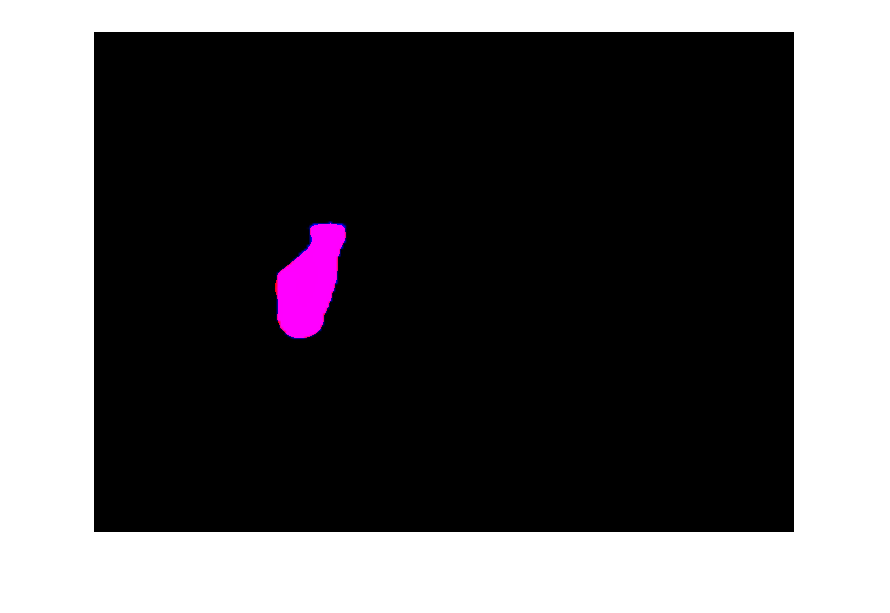

iou = 13.3866

bfs = 13.4672

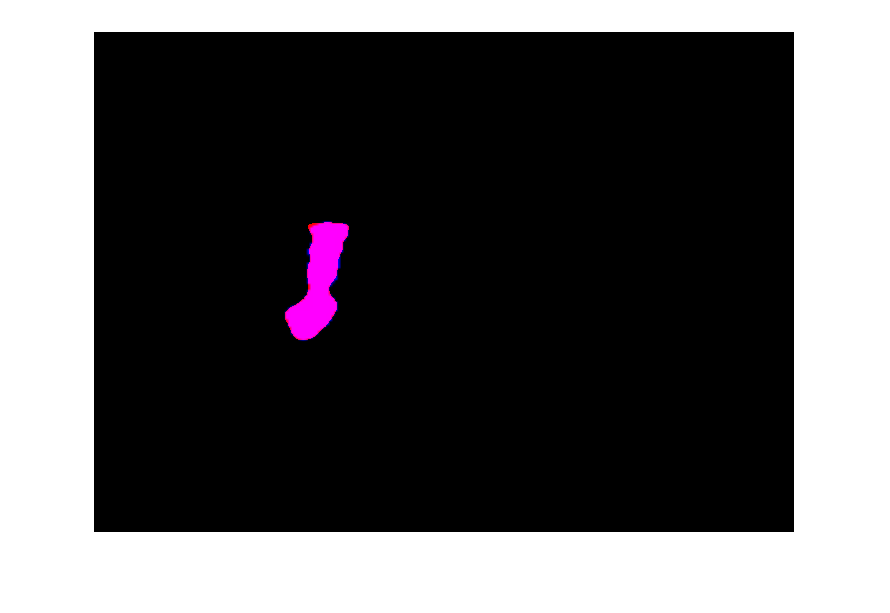

iou = 14.3380

bfs = 14.4255

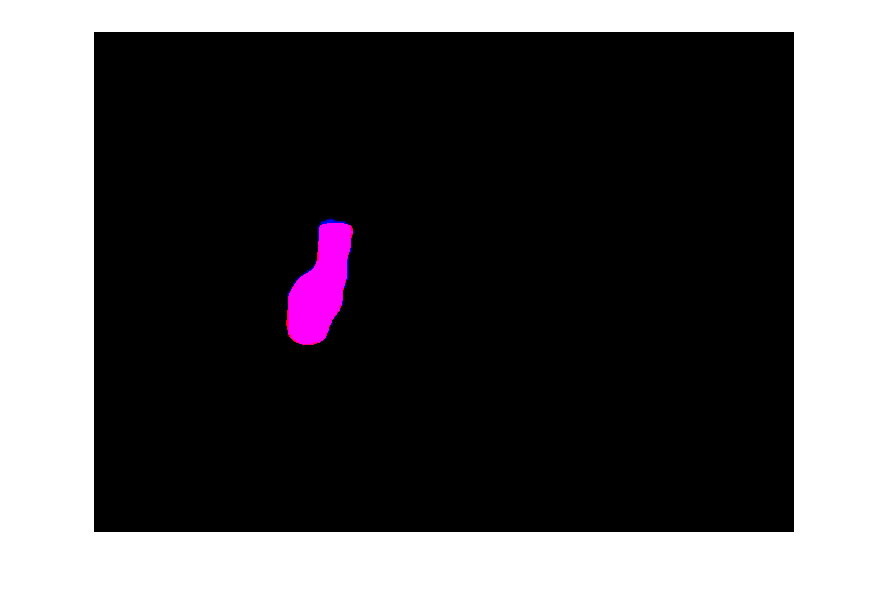

iou = 15.2777

bfs = 15.3784

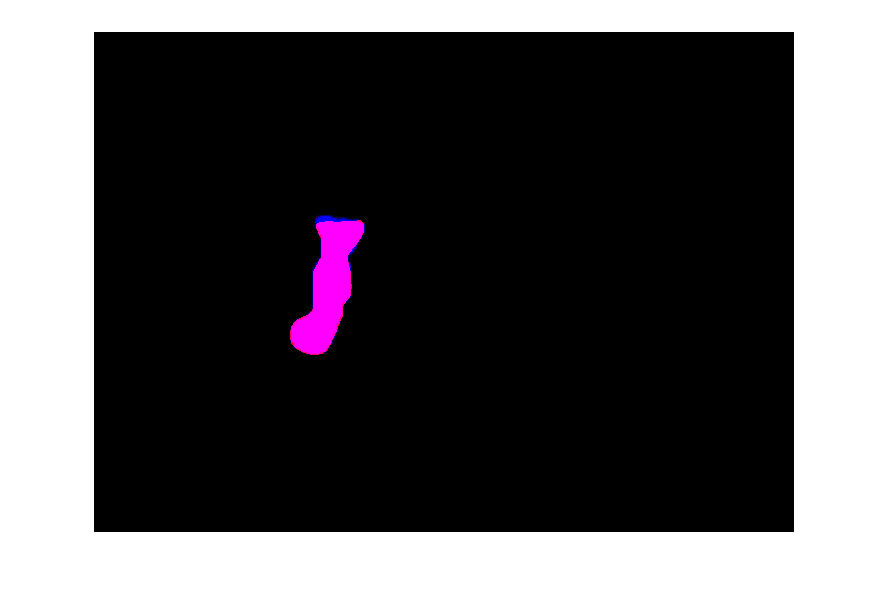

iou = 16.1639

bfs = 16.2999

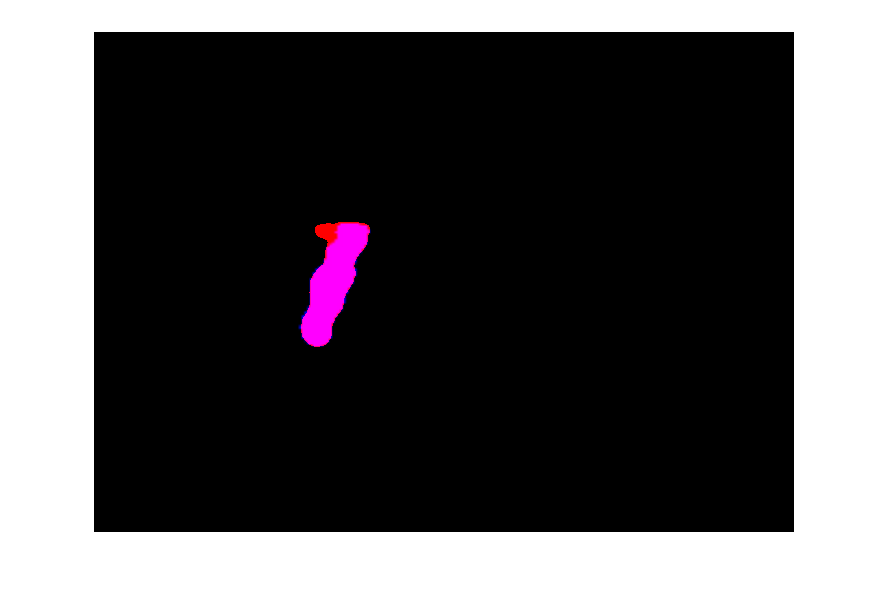

iou = 17.1277

bfs = 17.2668

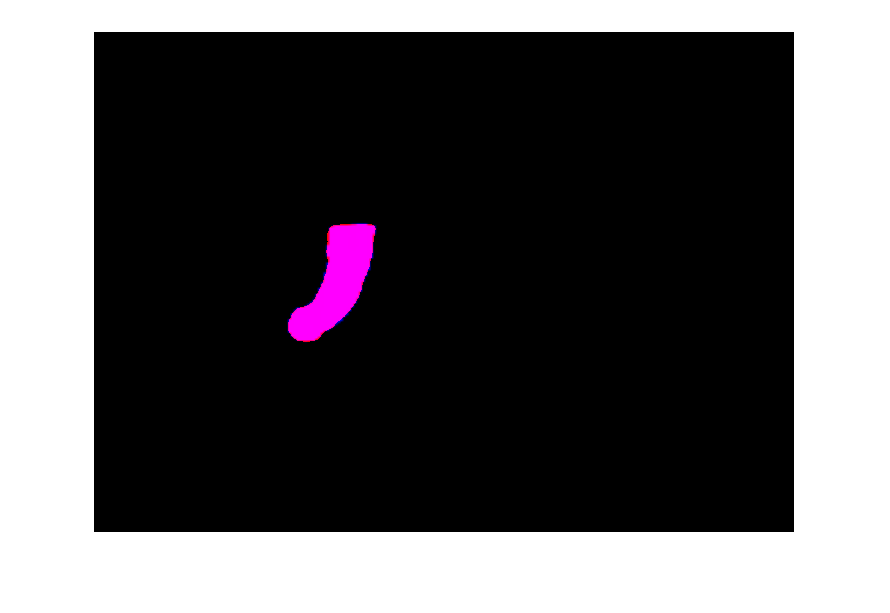

iou = 18.0847

bfs = 18.2298

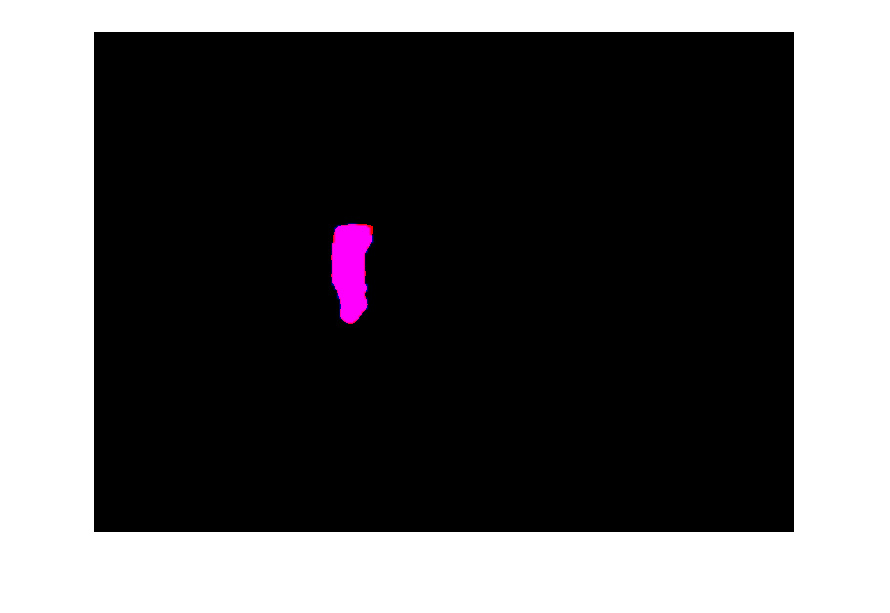

iou = 19.0251

bfs = 19.1800

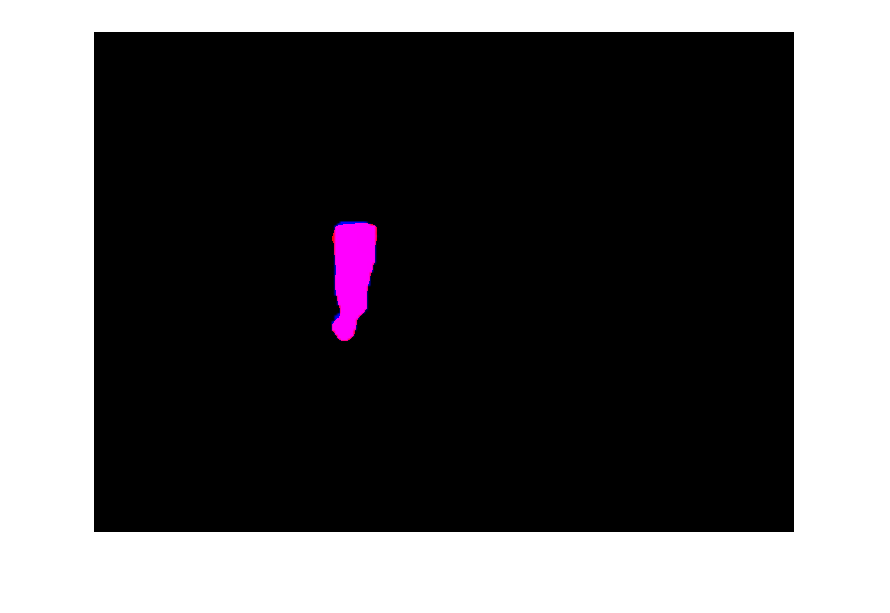

iou = 19.9916

bfs = 20.1494

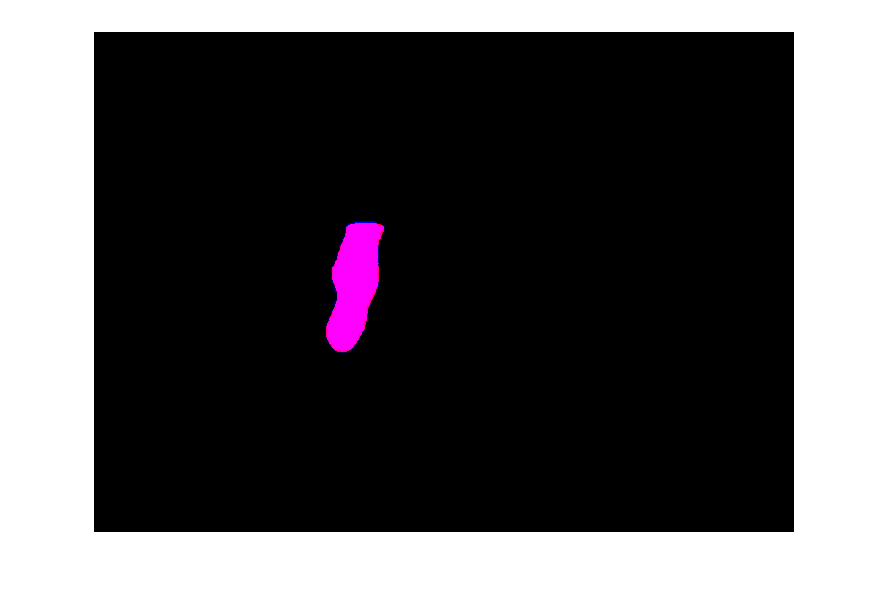

iou = 20.9532

bfs = 21.1155

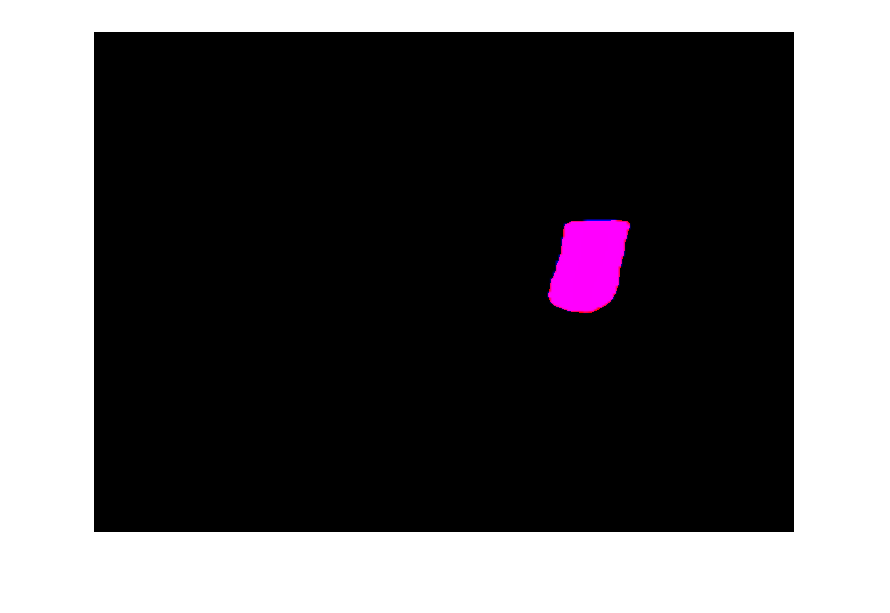

iou = 21.8886

bfs = 22.0625

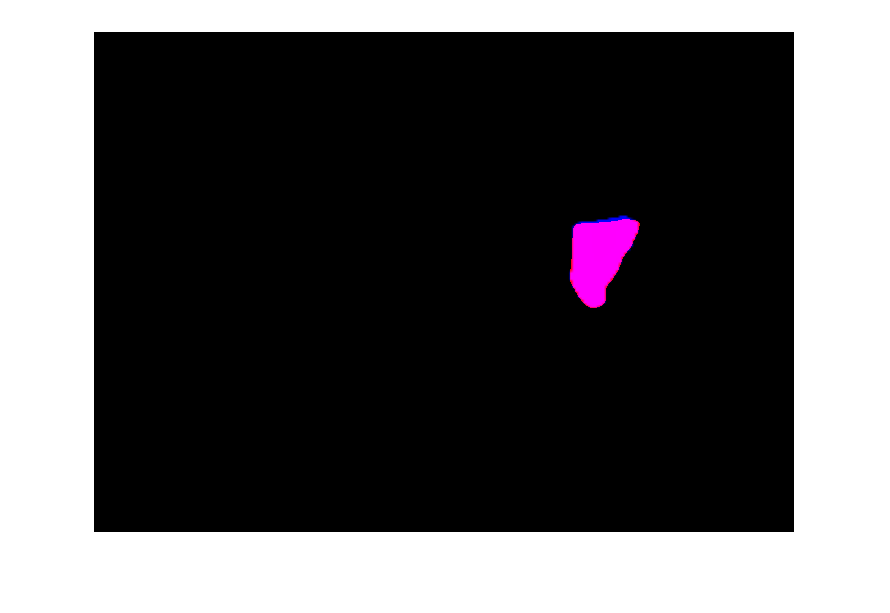

iou = 22.8356

bfs = 23.0151

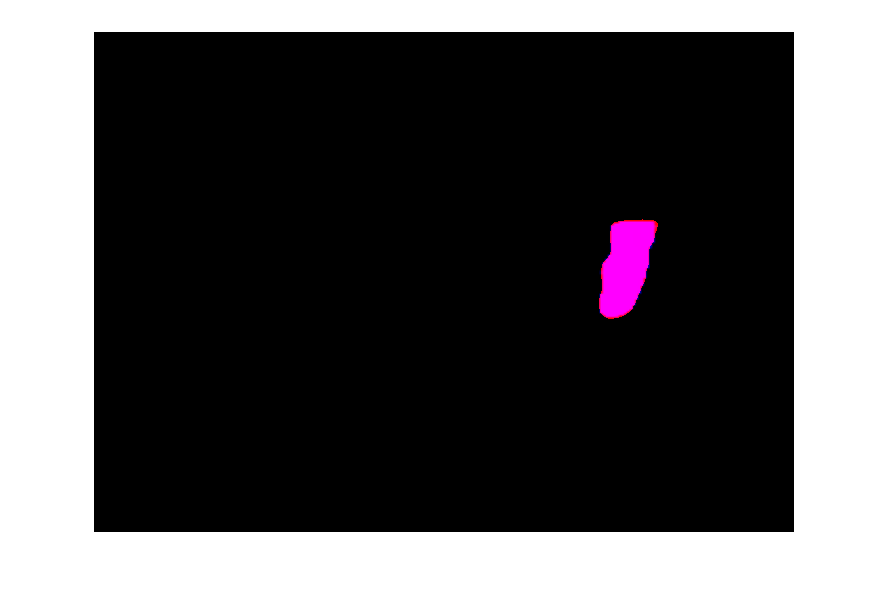

iou = 23.7865

bfs = 23.9747

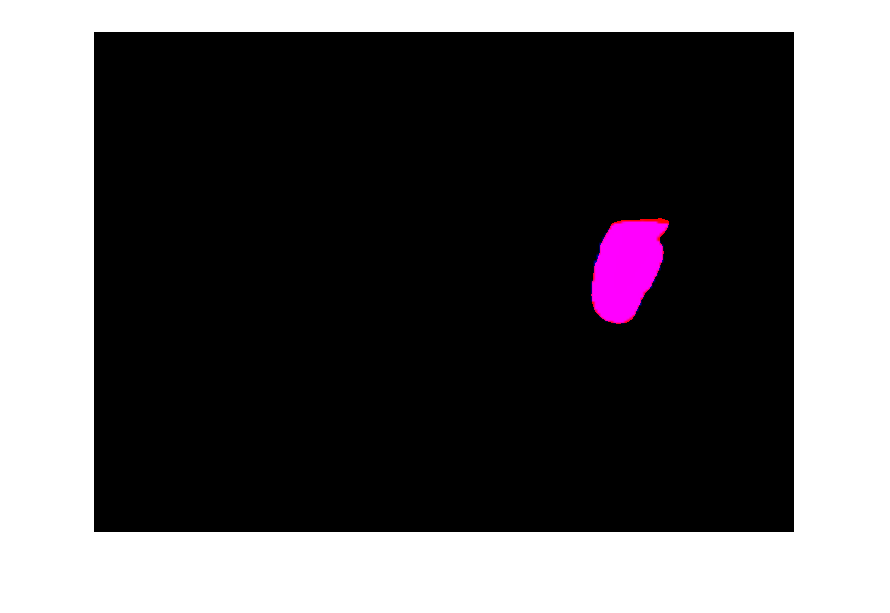

iou = 24.7349

bfs = 24.9328

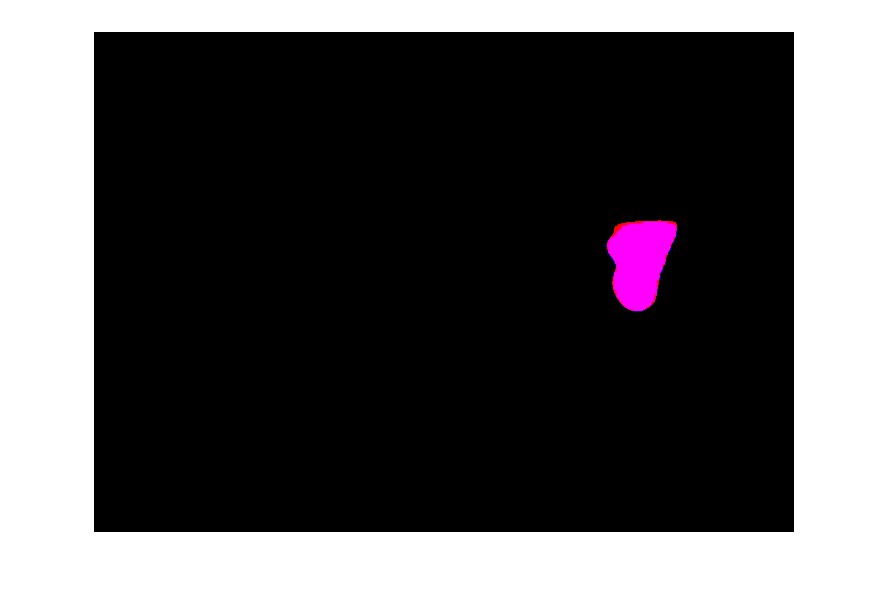

iou = 25.6970

bfs = 25.8987

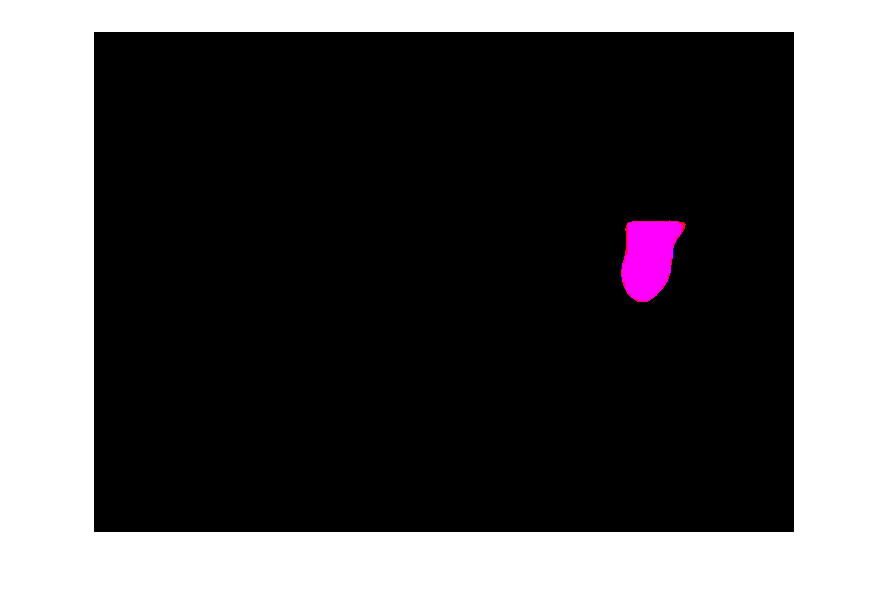

iou = 26.6632

bfs = 26.8694

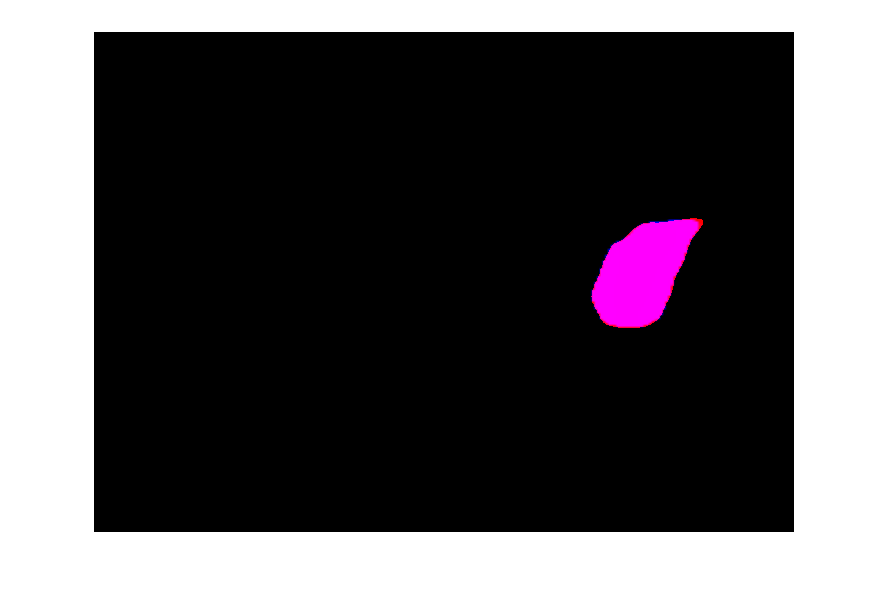

iou = 27.6095

bfs = 27.8275

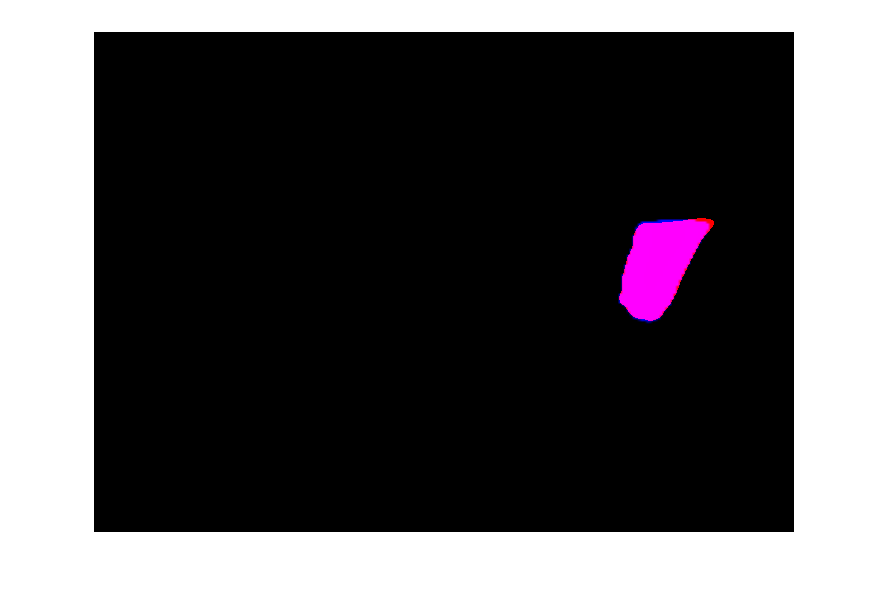

iou = 28.5571

bfs = 28.7819

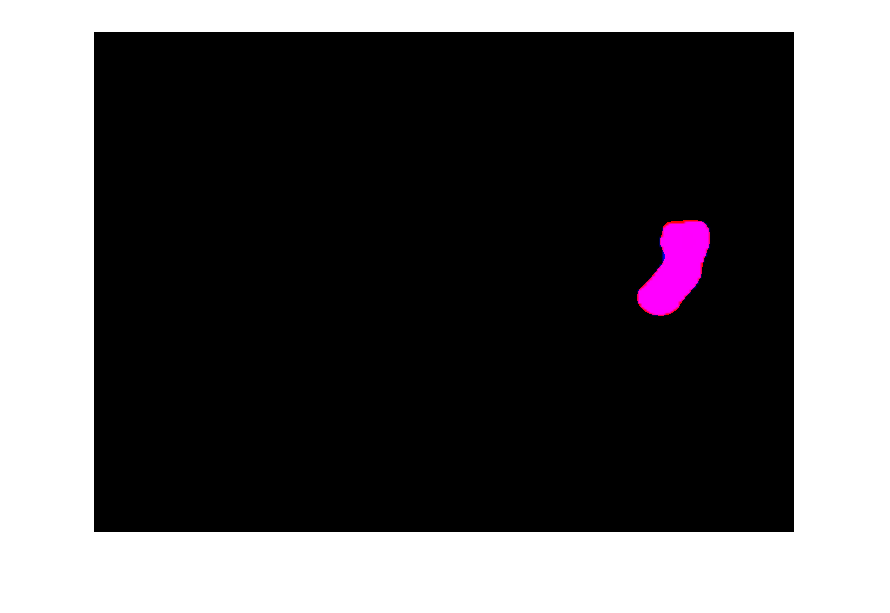

iou = 29.5202

bfs = 29.7485

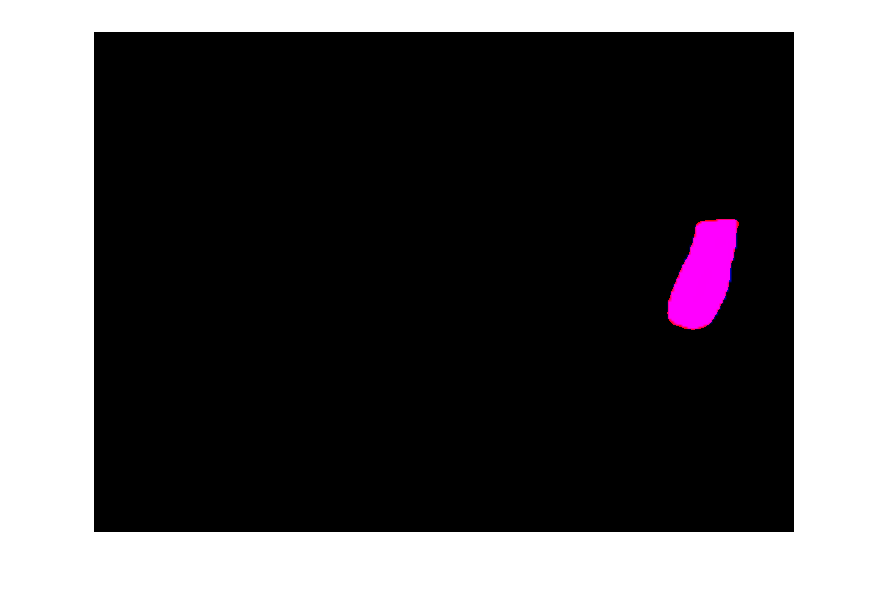

iou = 30.4691

bfs = 30.7028

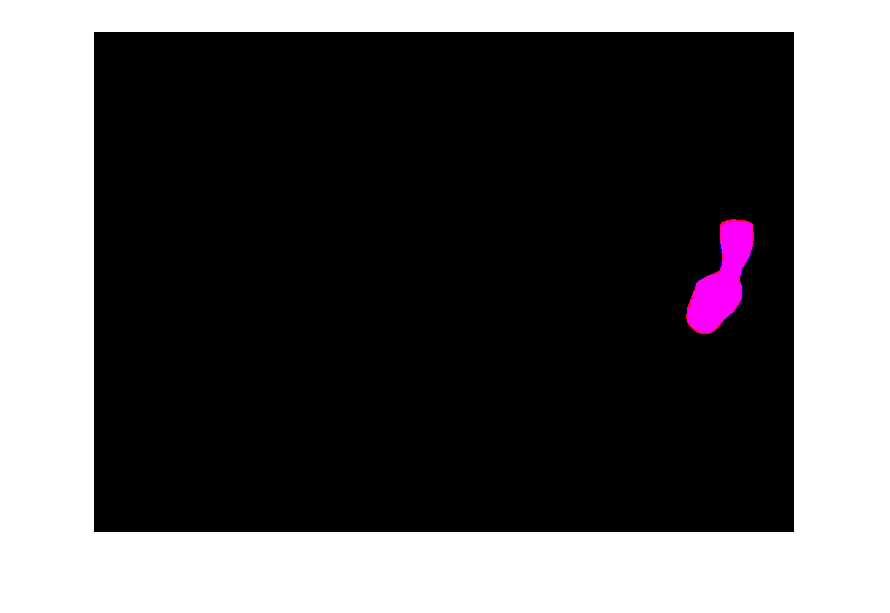

iou = 31.4000

bfs = 31.6451

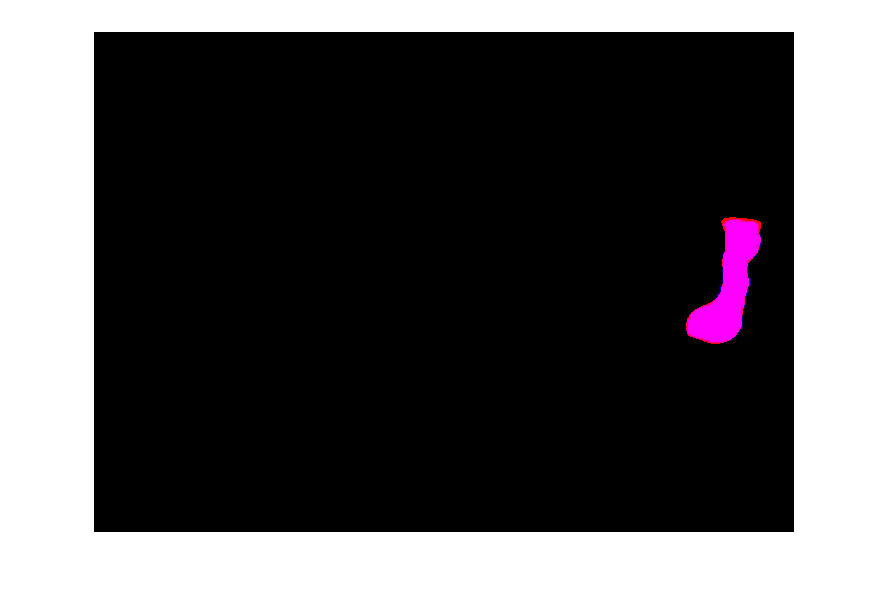

iou = 32.3624

bfs = 32.6120

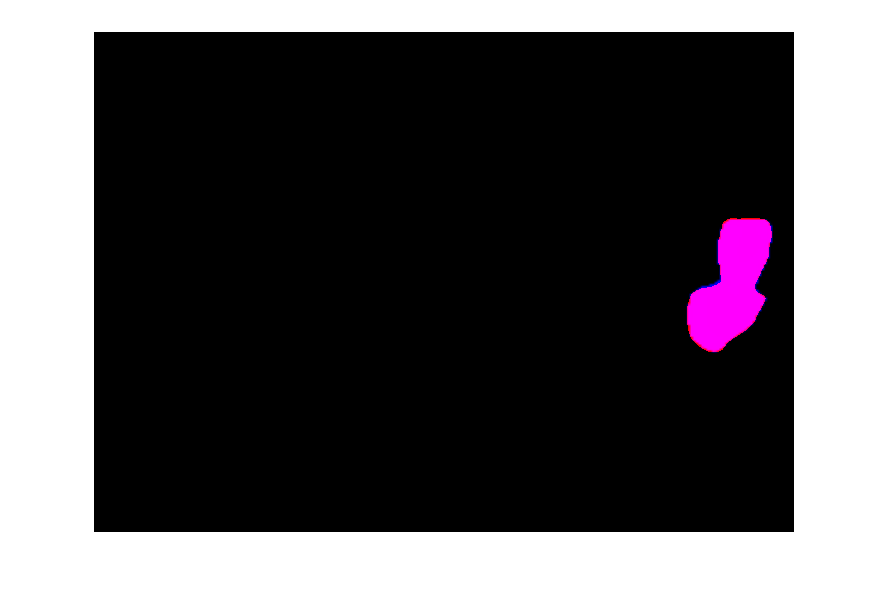

iou = 33.3242

bfs = 33.5779

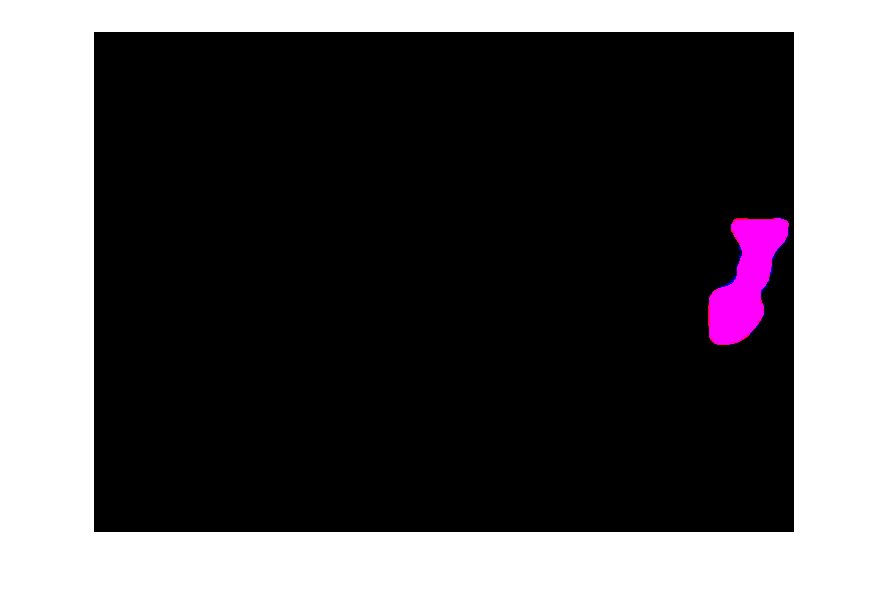

iou = 34.2938

bfs = 34.5498

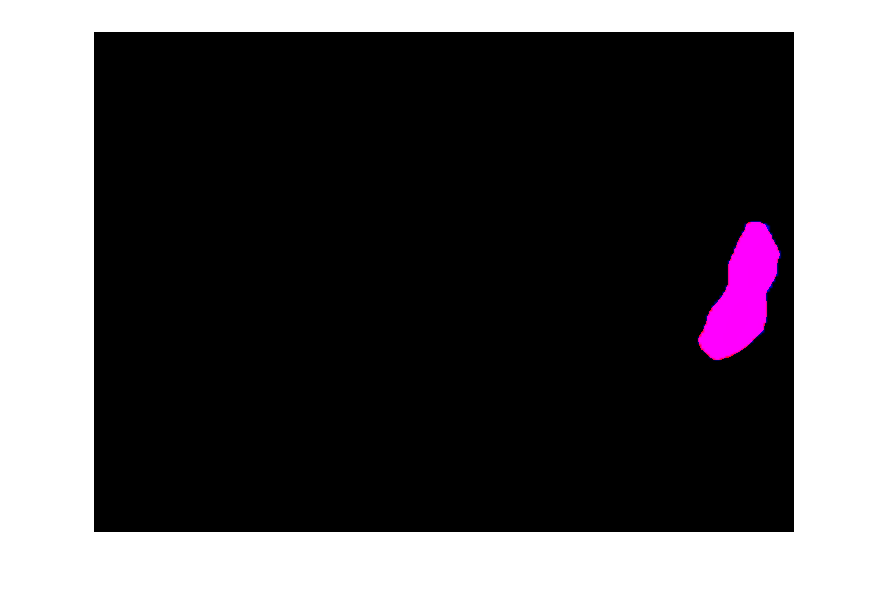

iou = 35.2605

bfs = 35.5193

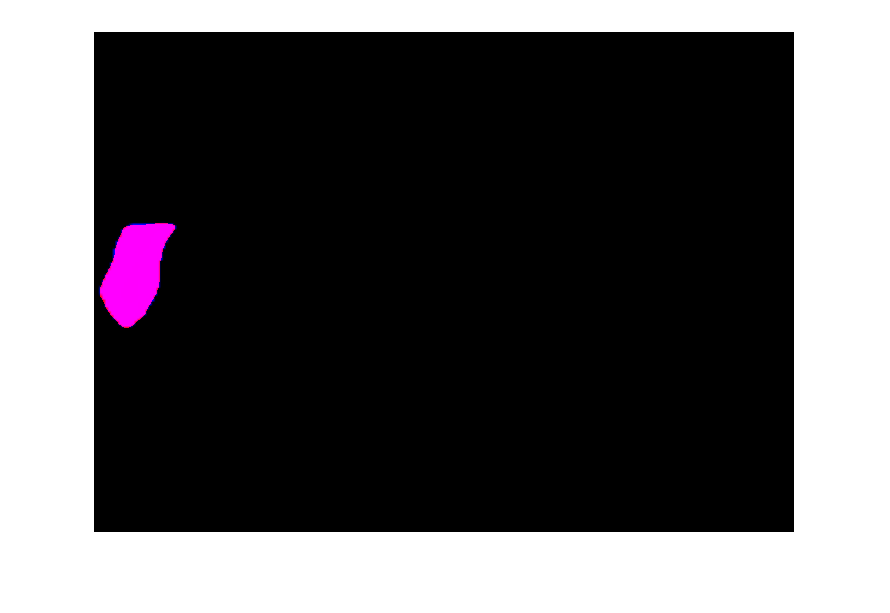

iou = 36.2090

bfs = 36.4746

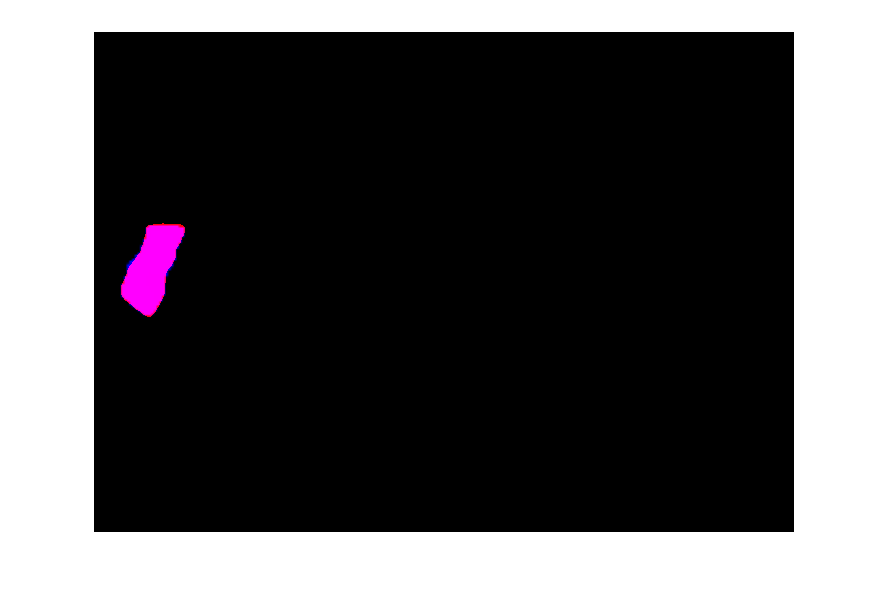

iou = 37.1663

bfs = 37.4405

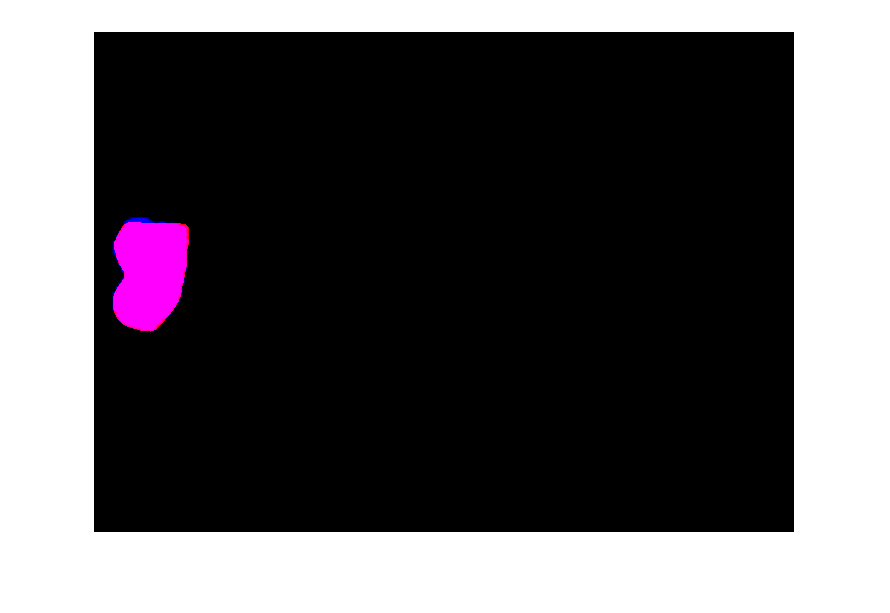

iou = 38.1347

bfs = 38.4117

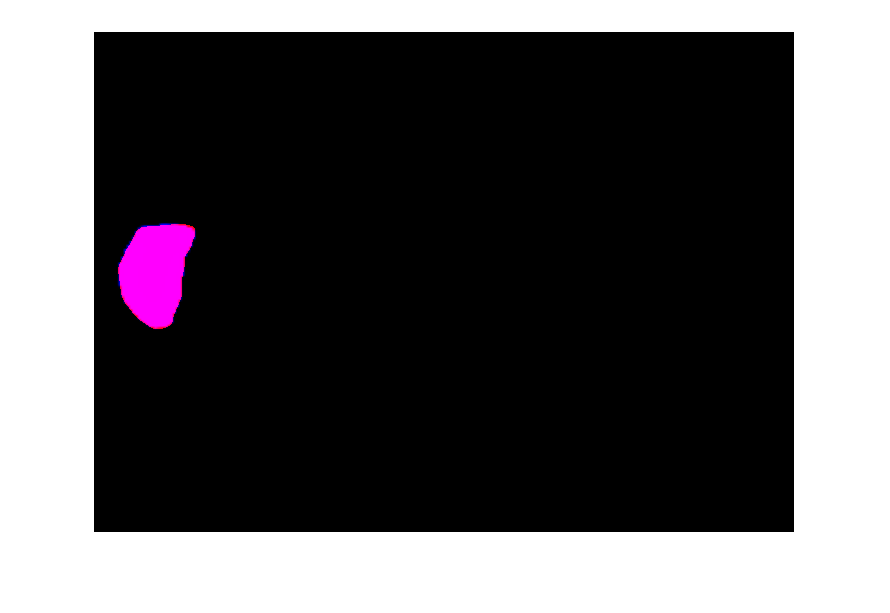

iou = 39.0583

bfs = 39.3552

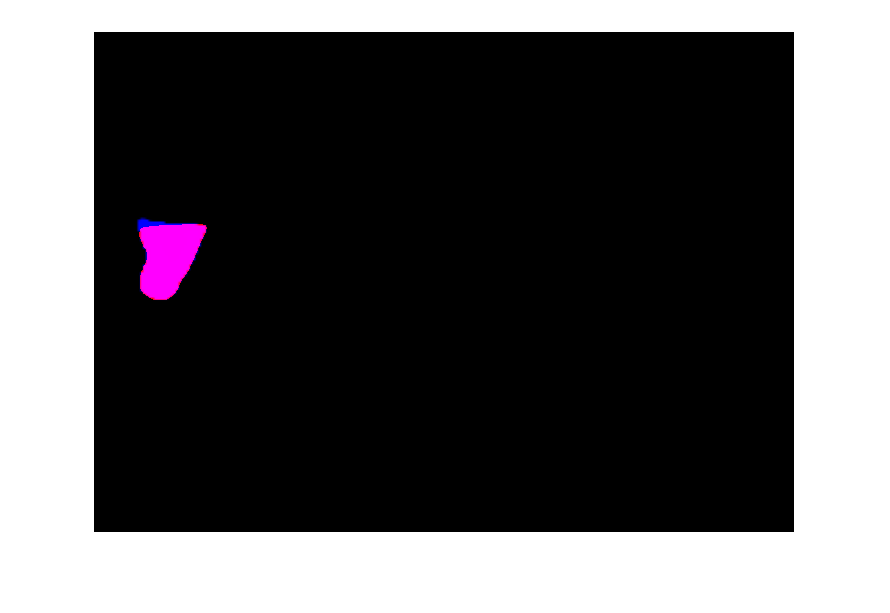

iou = 40.0283

bfs = 40.3271

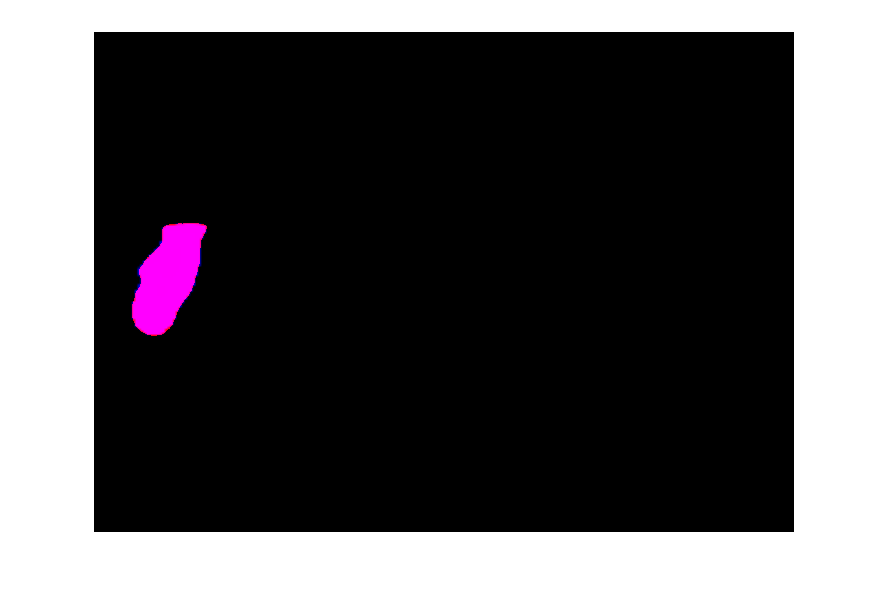

iou = 40.9618

bfs = 41.2764

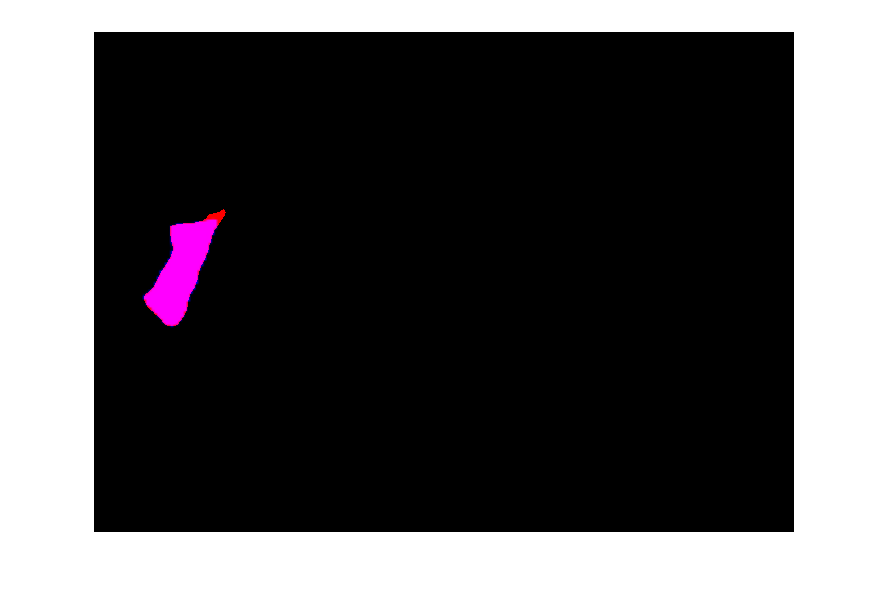

iou = 41.9213

bfs = 42.2414

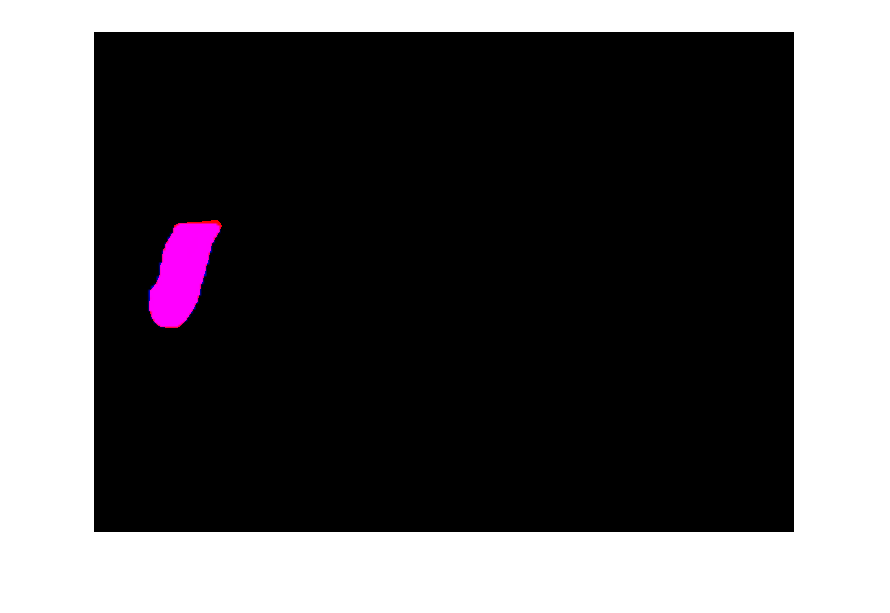

iou = 42.6660

bfs = 43.0803

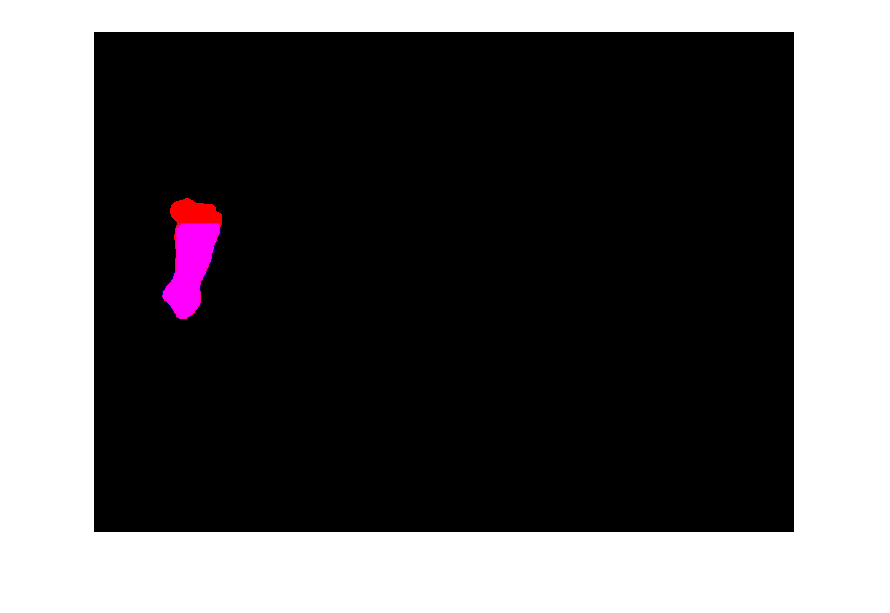

iou = 43.6395

bfs = 44.0560

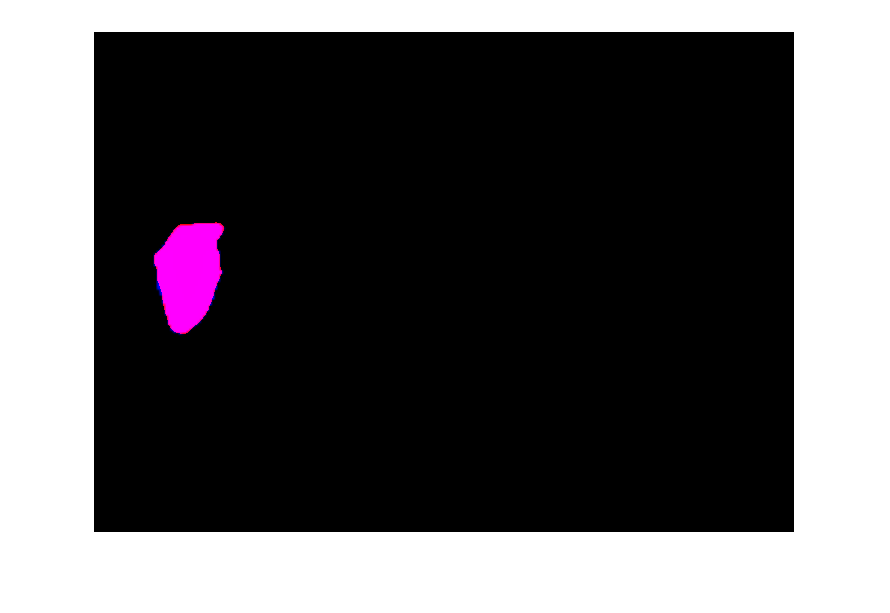

iou = 44.5967

bfs = 45.0176

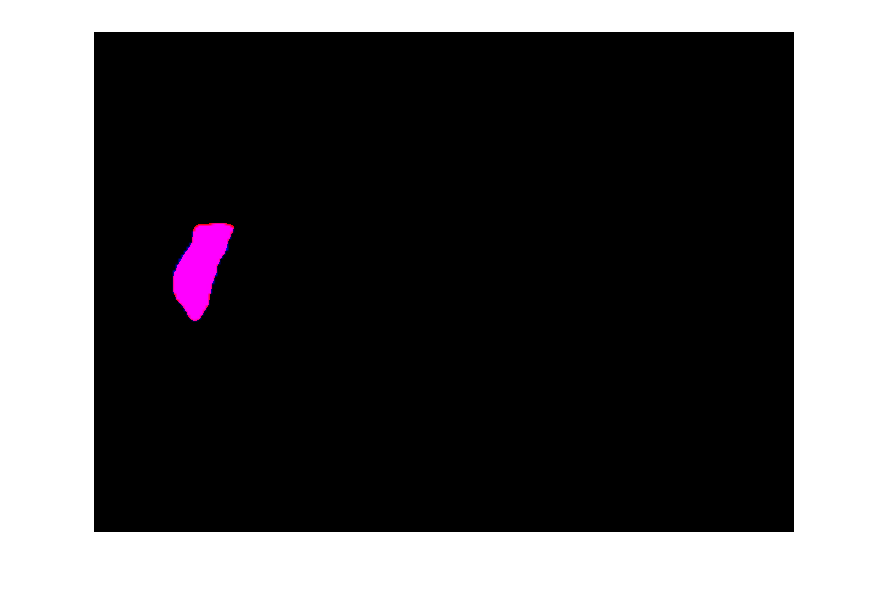

iou = 45.5585

bfs = 45.9840

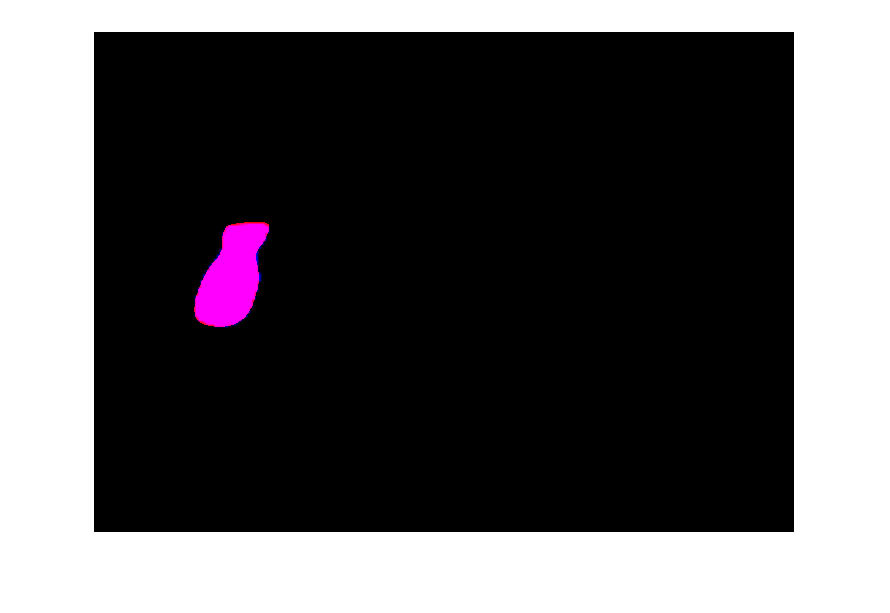

iou = 46.5186

bfs = 46.9481

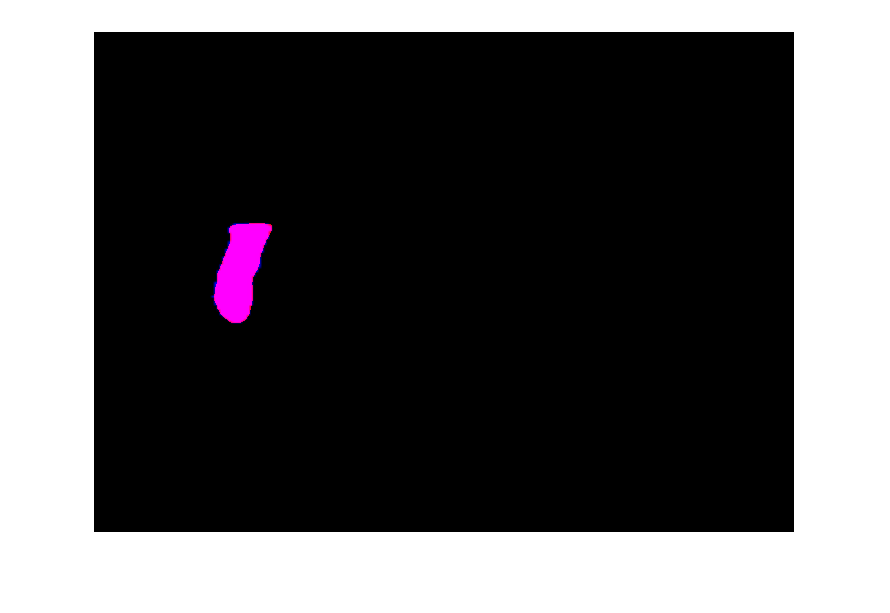

iou = 47.4870

bfs = 47.9182

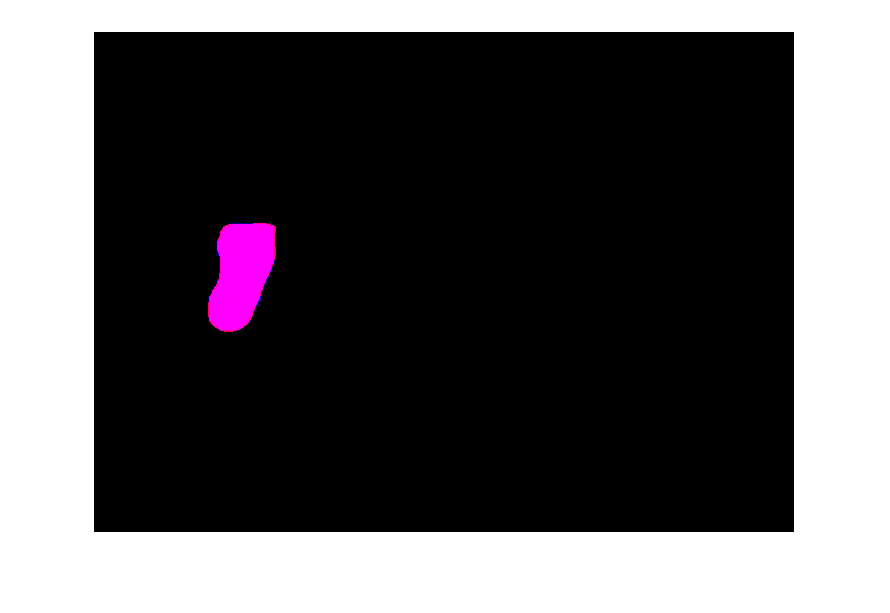


%loop to evaluate images
for i = 1:50
    figure;
    O = read(output);
    G = read(gtru);
    
    %convert image to binary label
    Ob = imbinarize(O);
    Gb = imbinarize(G);
    
    %compute score
    iou = jaccard(Ob,Gb)+iou
    bfs = bfscore(Ob,Gb,1)+bfs
    
    %show overlay
    G(:,:,3) = 0; G(:,:,2) = 0; G(:,:,1) = G(:,:,1);
    O(:,:,1) = 0; O(:,:,2) = 0; O(:,:,3) = O(:,:,3);
    OG = O+G;
    imshow(OG);
    hold off
end